## Introduction

In this scrip, we just try to test the calcualtion of residual（残差）. This version  uses 3 parameters: m, zeta and psi. The ranges of parameters come from fv1_range_confirming.

With using Bisection method can not get the correct parameter, we try to add the sampling frequency, and it becomes grid search method.

## Import data and previewing

data_name='p47_5s'

data_name = 'p47_5s'

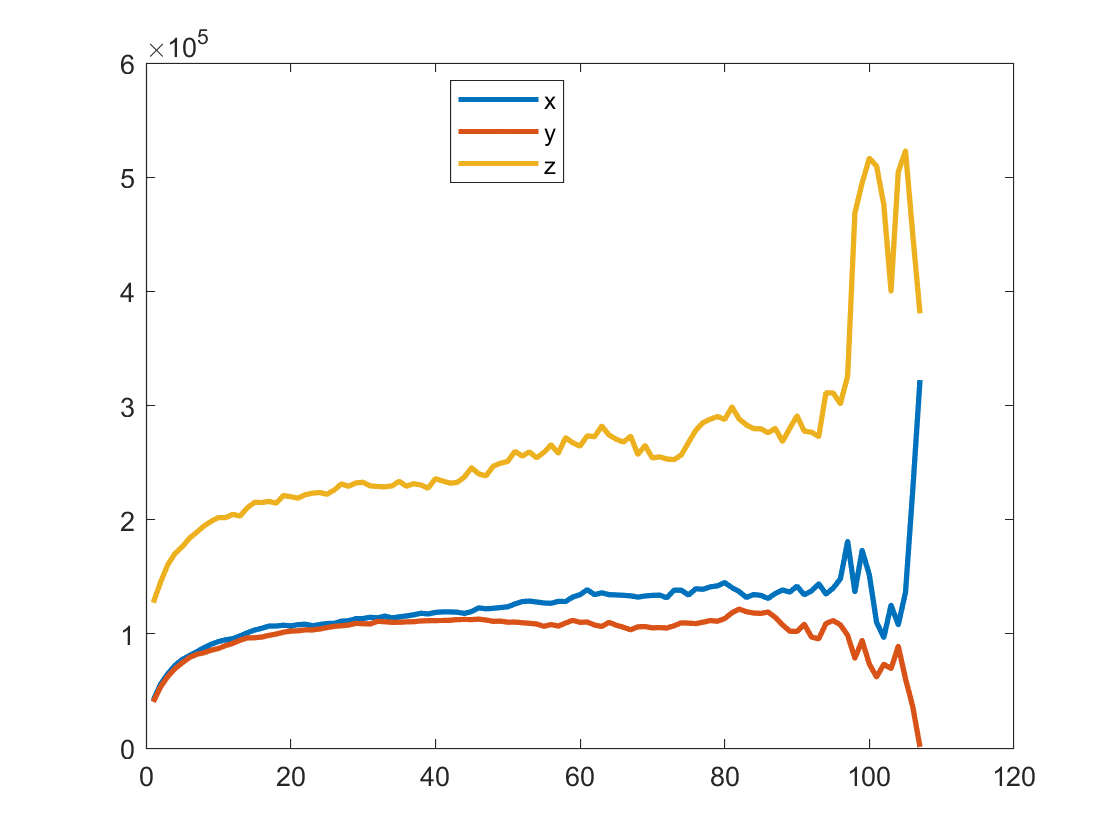

load(['C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\MSDData4Quan_20210905\MSD_',data_name,'_All.mat'])
plot(eval(['MSD_',data_name,'_All']).MSD_PP,'LineWidth',2)
legend('x','y','z','Location',"best");

cut down the declining part, we delete all data after the maximum one.

Reserved_lengths=zeros(3,1);
experiment_interval=5

experiment_interval = 5

X part

%experiment_MSDX=eval(['MSD_',data_name,'_All']).MSD_PP(:,1);
%max_experiment_MSDX=max(experiment_MSDX);
Reserved_lengths(1,1)=find(eval(['MSD_',data_name,'_All']).MSD_PP(:,1)==max(eval(['MSD_',data_name,'_All']).MSD_PP(:,1)));
interceptive_experiment_MSDX=1e-18*eval(['MSD_',data_name,'_All']).MSD_PP(1:Reserved_lengths(1,1),1);

Y part

%Reserved_lengths(2,1)=find(eval(['MSD_',data_name,'_All']).MSD_PP(:,2)==max(eval(['MSD_',data_name,'_All']).MSD_PP(:,2)));
%interceptive_experiment_MSDY=eval(['MSD_',data_name,'_All']).MSD_PP(1:Reserved_lengths(2,1),2);

Z part

%Reserved_lengths(3,1)=find(eval(['MSD_',data_name,'_All']).MSD_PP(:,3)==max(eval(['MSD_',data_name,'_All']).MSD_PP(:,3)))
%interceptive_experiment_MSDZ=eval(['MSD_',data_name,'_All']).MSD_PP(1:Reserved_lengths,3);

## Data Importing

import Time interval

delta=0.1;

import Total_experiment_number

Total_experiment_number=10;

data import

Reserved_length=Reserved_lengths(1,1);
interceptive_experiment_MSD=interceptive_experiment_MSDX;

## Initilizing parameter ranges

initialize H range

%H_min=0.52
%H_max=1.0
H=0.75

H = 0.7500

initialize m range

m_min=1e-9

m_min = 1.0000e-09

m_max=1e-5

m_max = 1.0000e-05

initialize zeta range

zeta_min=1e-8

zeta_min = 1.0000e-08

zeta_max=5e-5

zeta_max = 5.0000e-05

initialize psi range

psi_min=1e-8

psi_min = 1.0000e-08

psi_max=5e-5

psi_max = 5.0000e-05

## Initilaize grid searching

sampling_frequency=5;
sample_m=zeros(sampling_frequency,1);
sample_psi=zeros(sampling_frequency,1);
sample_zeta=zeros(sampling_frequency,1);

for i=1:sampling_frequency
    sample_m(i)=exp(log(m_min)+(log(m_max)-log(m_min))*(i-1)/sampling_frequency);
    sample_psi(i)=exp(log(psi_min)+(log(psi_max)-log(psi_min))*(i-1)/sampling_frequency);
    sample_zeta(i)=exp(log(zeta_min)+(log(zeta_max)-log(zeta_min))*(i-1)/sampling_frequency);
end

trying i_m=1, trying i_\psi=1, trying i_\zeta=1, total sampling number=5


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %
progress rate  80 %
progress rate  90 %
progress rate  100 %


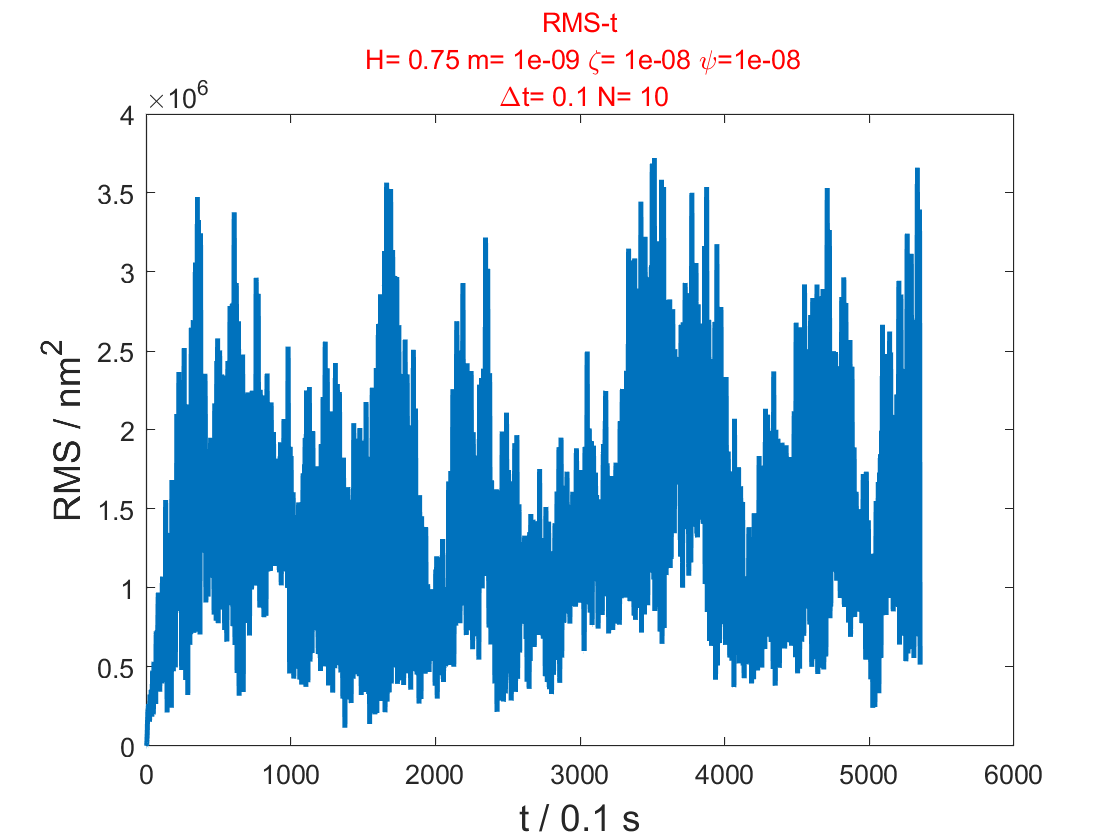

trying i_m=1, trying i_\psi=1, trying i_\zeta=2, total sampling number=5


explosion!


trying i_m=1, trying i_\psi=1, trying i_\zeta=3, total sampling number=5


explosion!


trying i_m=1, trying i_\psi=1, trying i_\zeta=4, total sampling number=5


explosion!


trying i_m=1, trying i_\psi=1, trying i_\zeta=5, total sampling number=5


explosion!


trying i_m=1, trying i_\psi=2, trying i_\zeta=1, total sampling number=5


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %
progress rate  50 %
progress rate  60 %
progress rate  70 %


progress rate  80 %
progress rate  90 %
progress rate  100 %


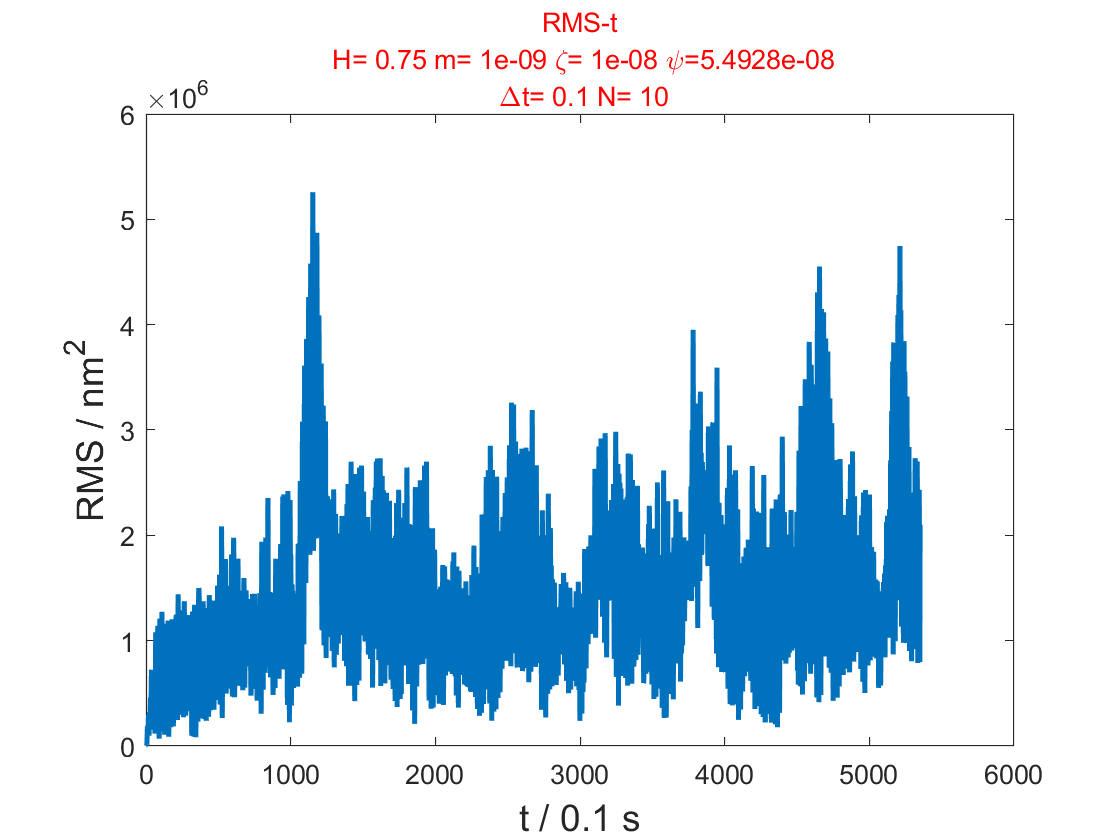

trying i_m=1, trying i_\psi=2, trying i_\zeta=2, total sampling number=5


explosion!


trying i_m=1, trying i_\psi=2, trying i_\zeta=3, total sampling number=5


explosion!


trying i_m=1, trying i_\psi=2, trying i_\zeta=4, total sampling number=5


explosion!


trying i_m=1, trying i_\psi=2, trying i_\zeta=5, total sampling number=5


explosion!


trying i_m=1, trying i_\psi=3, trying i_\zeta=1, total sampling number=5


progress rate  10 %
progress rate  20 %
progress rate  30 %
progress rate  40 %


residual_compare=zeros(sampling_frequency,sampling_frequency,sampling_frequency);
for i_m=1:sampling_frequency
    m=sample_m(i_m);
    for i_psi=1:sampling_frequency
        psi=sample_psi(i_psi,1);
        for i_zeta=1:sampling_frequency
            zeta=sample_zeta(i_zeta,1);
            disp(['trying i_m=',num2str(i_m,1),', trying i_\psi=',num2str(i_psi),', trying i_\zeta=',num2str(i_zeta),', total sampling number=',num2str(sampling_frequency)])
            residual_compare(i_m,i_psi,i_zeta)=function_residual_calculating_fv2(Reserved_length,experiment_interval,interceptive_experiment_MSD,psi,zeta,H,m,delta,Total_experiment_number);
        end
    end
end

index system: find the minimum of residuals and its lication.

[mini,best_linear_location]=min(residual_compare,[],'all','linear');
[best_m,best_psi_zeta]=find(residual_compare==mini);
sampling_size=[sampling_frequency,sampling_frequency];
[best_psi,best_zeta]=ind2sub(sampling_size,best_psi_zeta);
good_parameter_location=find(residual_compare<=10*min(residual_compare,[],'all'));
disp(['best m near ',num2str(sample_m(best_m))])
disp(['best psi near ',num2str(sample_psi(best_psi))])
disp(['best zeta near ',num2str(sample_zeta(best_zeta))])

saving

saving_loacation='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\数据模拟\P.S.test';
save([saving_loacation,'\data\parameterselection','m,psi,zeta',num2str(clock),'.mat'],'residual_compare','sample_m','sample_psi','sample_zeta');